# Rote method

## Taks 1

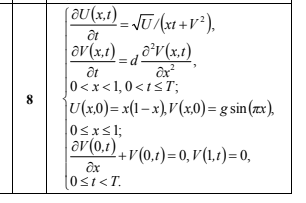

global k g D N N1 NN x
% параметри модельної задачі :
k=1; g=1; d=1;
h = 0.01;
% параметри різницевої схеми :
N=41; N1=N-1; h=1./N1; x=[0:h:1]; x(N)=1; NN=2.*N; NN1=NN-1;
tau=1e-2; M=1000;
D=1./(d.*h);
% формування початкових умов при t=0 :
Y=lr5_u0;
Y0=Y; % запам'ятовуємо для побудови графіку розв'язку в t=0
tk=0;
for j=1:M
    % знаходження розв'язку на відрізку [t0,tk] :
    t0=tk;
    tk=t0+tau;
    y0=(Y(2:NN1))';
    [t,y]=ode45(@lr5_ff,[t0 tk],Y);
    rf=size(y); m=rf(1);
    Y(1)=lr5_my1(tk);
    for i=2:NN1
        Y(i)=y(m,i-1);
    end
    Y(NN)=lr5_my2(tk);
    if j*2==M
        Y1=Y; % запам'ятовуємо для побудови графіку розв'язку в t=M*tau/2
    end
end
% побудова графіків розв'язку при t=0, M*tau/2, M*tau :
t=M.*tau; t1=0.5.*t; T1=num2str(t1); T=num2str(t);
plot(x,Y0(1:N),'b.-',x,Y1(1:N),'k.--',x,Y(1:N),'r*-');

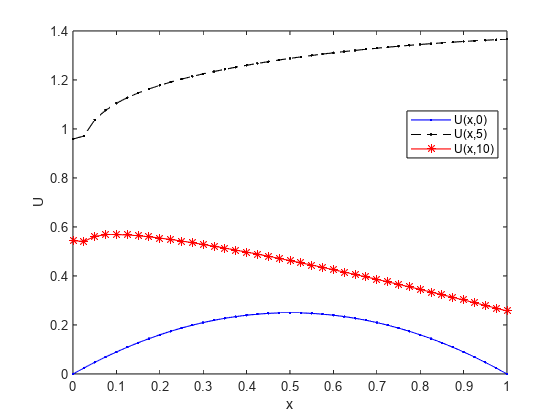

xlabel('x');
ylabel('U');
legend('U(x,0)',strcat('U(x,',T1,')'),strcat('U(x,',T,')'),'Location','Best');

pause
plot(x,Y0(N+1:NN),'b.-',x,Y1(N+1:NN),'k.--',x,Y(N+1:NN),'r*-');
xlabel('x');
ylabel('V');
legend('V(x,0)',strcat('V(x,',T1,')'),strcat('V(x,',T,')'),'Location','Best');
pause

ОСНОВНА МОДИФІКАЦІЯ. Метод той самий, хіба що інші функції + переписав lr5_ff повністю

function u=lr5_u0
    % Функції U(x,0), V(x,0)
    global N x
    for i=1:N
        u(i)=x(i).*(1 - x(i));
        u(i+N)=sin(pi.*x(i));
    end
end

function y=lr5_my1(t)
    % Функція U(0,t)
    y=sin(-t);
end

function y=lr5_my2(t)
    % Функція V(1,t)
    y=0;
end




function f=lr5_ff(t, UU)
    % Опис правої частини системи ЗДР
    global k g D N N1 NN x
    f=zeros(n,1); yy1=lr5_my1(t); yyNN=lr5_my2(t);

    % Розбиваємо на 2 масиви, щоб не працювати через
    % незрозумілі індекси
    V = UU(N+1:end);  
    U = UU(1:N);

    % dU/dt = sqrt(U) / (x*t + V^2)
    for i=1:N
        if i == 1
            f(i) = yy1;  % U boundary condition at x = 0
        else
            f(i) = sqrt(U(i)) / (x(i)*t + V(i)^2);
        end
    end
    
    % dV/dt = 17 * dV^2/dx^2
    for i=1:NN - N
        if i == 1  % Boundary condition - left
            f(i + N) = 17 * (V(i+1)-V(i)) / (x(2)-x(1))^2;
        elseif i == NN - N  % Boundary condition - right
            f(i + N) = yyNN;
        else
            f(i + N) = 17 * (V(i+1)-2*V(i)+V(i-1)) / (x(2)-x(1))^2;
        end
    end
end